a = 1 + mod(137,3);

%Q1)
%2)
N = 1024;
f = (0:N-1)/N

f =          0    0.0010    0.0020    0.0029    0.0039    0.0049    0.0059    0.0068    0.0078    0.0088    0.0098    0.0107    0.0117    0.0127    0.0137    0.0146    0.0156    0.0166    0.0176    0.0186    0.0195    0.0205    0.0215    0.0225    0.0234    0.0244    0.0254    0.0264    0.0273    0.0283    0.0293    0.0303    0.0312    0.0322    0.0332    0.0342    0.0352    0.0361    0.0371    0.0381    0.0391    0.0400    0.0410    0.0420    0.0430    0.0439    0.0449    0.0459    0.0469    0.0479


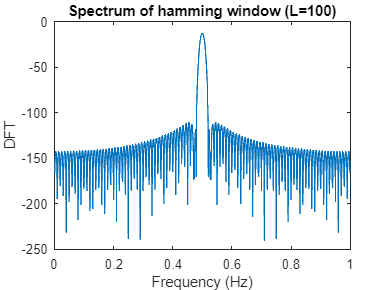

L = 100;
dft = fftshift(fft(hamming(L),N));
plot(f,20*log(abs(dft)/L))
xlabel('Frequency (Hz)')
ylabel('DFT')
title('Spectrum of hamming window (L=100)')

N = 1024;
f = (0:N-1)/N

f =          0    0.0010    0.0020    0.0029    0.0039    0.0049    0.0059    0.0068    0.0078    0.0088    0.0098    0.0107    0.0117    0.0127    0.0137    0.0146    0.0156    0.0166    0.0176    0.0186    0.0195    0.0205    0.0215    0.0225    0.0234    0.0244    0.0254    0.0264    0.0273    0.0283    0.0293    0.0303    0.0312    0.0322    0.0332    0.0342    0.0352    0.0361    0.0371    0.0381    0.0391    0.0400    0.0410    0.0420    0.0430    0.0439    0.0449    0.0459    0.0469    0.0479


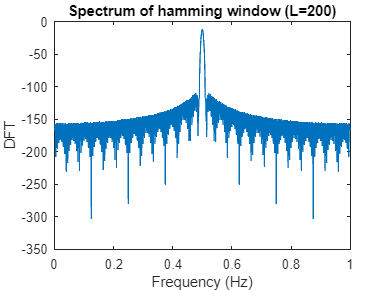

L = 200;
dft = fftshift(fft(hamming(L),N));
plot(f,20*log(abs(dft)/L))
xlabel('Frequency (Hz)')
ylabel('DFT')
title('Spectrum of hamming window (L=200)')

N = 1024;
f = (0:N-1)/N

f =          0    0.0010    0.0020    0.0029    0.0039    0.0049    0.0059    0.0068    0.0078    0.0088    0.0098    0.0107    0.0117    0.0127    0.0137    0.0146    0.0156    0.0166    0.0176    0.0186    0.0195    0.0205    0.0215    0.0225    0.0234    0.0244    0.0254    0.0264    0.0273    0.0283    0.0293    0.0303    0.0312    0.0322    0.0332    0.0342    0.0352    0.0361    0.0371    0.0381    0.0391    0.0400    0.0410    0.0420    0.0430    0.0439    0.0449    0.0459    0.0469    0.0479


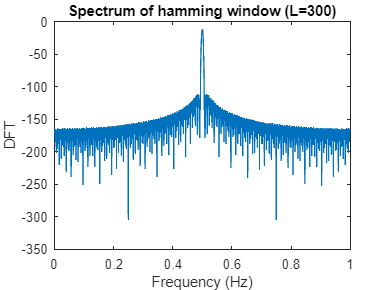

L = 300;
dft = fftshift(fft(hamming(L),N));
plot(f,20*log(abs(dft)/L))
xlabel('Frequency (Hz)')
ylabel('DFT')
title('Spectrum of hamming window (L=300)')

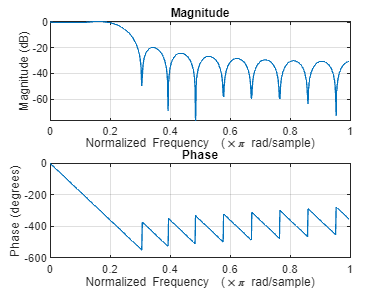

%Q2)
wc = (pi/4);
L = 21;
% order = L - 1;
b = fir1(20,1/4,'low',rectwin(L));
freqz(b,1,512)

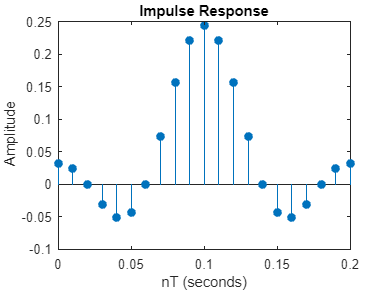

impz(b,1,[],100)

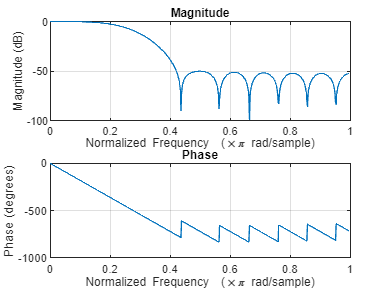

b1 = fir1(20,1/4,'low',hamming(L));
freqz(b1,1,512)

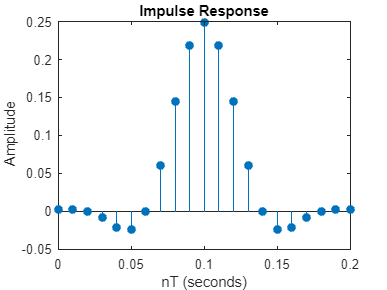

impz(b1,1,[],100)

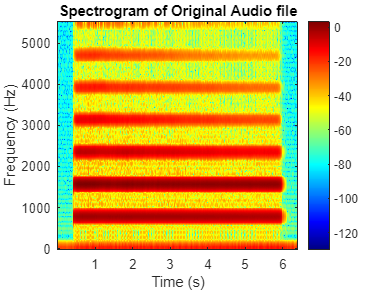

%Q3)
%Spectrogram
figure;
% Step 1: Read the audio file
audioFilePath = 'instru3.wav';  % Replace with the path to your audio file
[y, fs] = audioread(audioFilePath);

% Step 2: Define spectrogram parameters
windowSize = 100;  % Size of the analysis window (e.g., 256 samples)
overlap = 10;     % Overlap between consecutive windows (e.g., 50% overlap)
nfft = 512;        % Number of FFT points (higher values give finer frequency resolution)

% Step 3: Compute the spectrogram
[S, F, T] = spectrogram(y, hamming(windowSize), overlap,nfft,fs);

% Step 4: Plot the spectrogram
figure;
imagesc(T, F, 20*log10(abs(S)));  % Convert to dB scale
axis xy;  % Flip the y-axis to have lower frequencies at the bottom
xlabel('Time (s)');
ylabel('Frequency (Hz)');
title('Spectrogram of Original Audio file');
colorbar;  % Display a colorbar showing the magnitude in dB
colormap('jet');

% Step 2: Compute the FFT of the audio signal
N = length(y);  % Length of the audio signal
Y = fft(y);     % Compute the FFT

% Step 3: Find the fundamental frequency
frequencies = (0:N-1)*(fs/N);  % Frequency axis
magnitude = 20*log10(abs(Y));            % Magnitude of FFT
[~, idx] = max(magnitude(1:N/2+1));  % Find the index of the maximum magnitude
fundamentalFrequency = frequencies(idx);  % Fundamental frequency in Hz

% Display the results
fprintf('Fundamental Frequency: %.2f Hz\n', fundamentalFrequency);

Fundamental Frequency: 1566.24 Hz


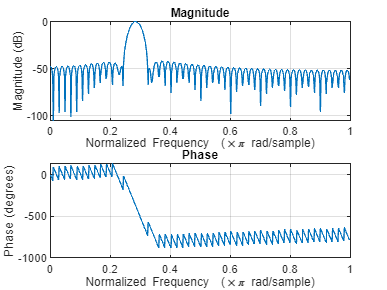

b2 = fir1(99,[(1566.24-10)/(fs/2) (1566.24+10)/(fs/2)]); %0.2 , 0.3
%known that fs = 1575
%normalised by fs/2 ie 
freqz(b2,1,512)

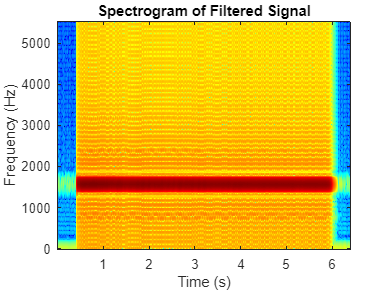

% Apply the filter to extract the fundamental frequency
filtered_signal = filter(b2,1,y);

% Write the filtered signal to a new WAV file
audiowrite('filtered_instru3.wav', filtered_signal, fs);

% Listen to the filtered audio
%sound(filtered_signal, fs);

% Compute and plot the spectrogram of the filtered signal
[S_filtered, F_filtered, T_filtered] = spectrogram(filtered_signal, hamming(windowSize), overlap, nfft, fs);

figure;
imagesc(T_filtered, F_filtered, 20*log10(abs(S_filtered)));
axis xy;
xlabel('Time (s)');
ylabel('Frequency (Hz)');
title('Spectrogram of Filtered Signal');
colormap('jet');